clear; 
clc;

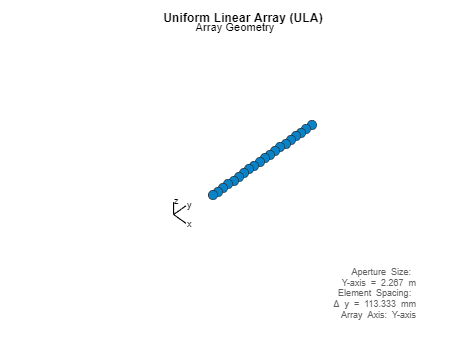


% Define the environment
room_dim = [10, 10, 3];

% Speaker positions (r, azimuth angle, elevation angle)
speakers = [1, 25, 10; 
            5, 40, -10;
            3, 20, 0;];
num_sources = 3;

% Microphone array definition
% Define Microphone Element (Omnidirectional)
microphone = phased.OmnidirectionalMicrophoneElement('FrequencyRange', [20 4000]);

% Define Speed of Sound
c = 340;  % Speed of sound in m/s

% Define ULA Parameters
Nele = 20;  % Number of elements
f_center = 1500; % Center frequency in Hz (adjustable based on signal)
lambda = c / f_center; % Wavelength at center frequency
d = lambda / 2;  % Element spacing (λ/2 ensures proper spatial sampling)

% Create the ULA (Uniform Linear Array)
ula = phased.ULA('NumElements', Nele, 'ElementSpacing', d, 'Element', microphone);

% Get Element Positions
positions = getElementPosition(ula);

% Visualize the ULA
viewArray(ula);
title('Uniform Linear Array (ULA)');



% Define angles of arrival
ang_dft = [20; 0];
ang_cleanspeech = [30; 0];
ang_laughter = [40; 0];

% Simulation parameters
fs = 22050;  % Sampling frequency
t_duration = 10;  % Signal duration (seconds)
t = 0:1/fs:t_duration-1/fs;
NSampPerFrame = 1000;
NTSample = t_duration * fs;
sigArray = zeros(NTSample,Nele);

% [x1,fs1]=audioread("Female4.wav");
% [x2,fs2]=audioread("Female2.wav");
% [x3,fs3]=audioread("Female3.wav");
% x1=resample(x1,fs,fs1);
% x2=resample(x2,fs,fs2);
% audiowrite("Male.wav",x1,fs);
% audiowrite("Female.wav",x2,fs);

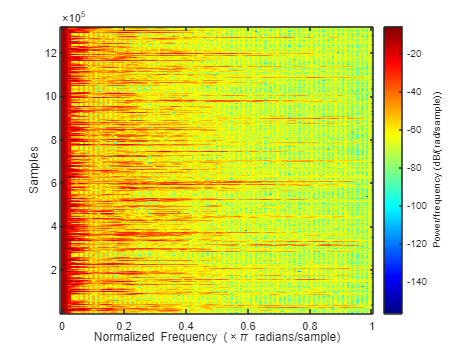

[y1, fs1]=audioread("Female4.wav");
[y2, fs2]=audioread("Female3.wav");
[y3, fs3]=audioread("Female2.wav");
spectrogram(y1,128,120,256)
colormap(jet);

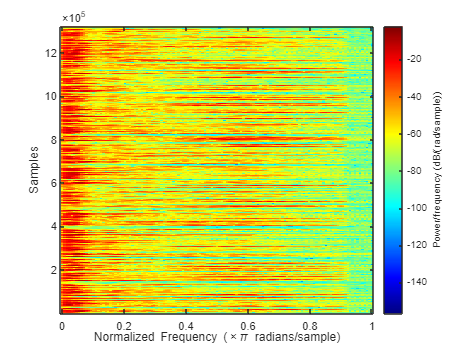

spectrogram(y2,128,120,256)
colormap(jet);

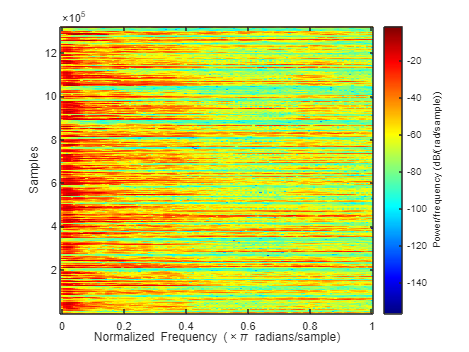

spectrogram(y3,128,120,256)
colormap(jet);

% Load and process the audio files
dftFileReader = dsp.AudioFileReader("Female4.wav", 'SamplesPerFrame', NSampPerFrame);
speechFileReader = dsp.AudioFileReader('Female2.wav', 'SamplesPerFrame', NSampPerFrame);
laughterFileReader = dsp.AudioFileReader('Female3.wav', 'SamplesPerFrame', NSampPerFrame);

% Initialize wideband collector
collector = phased.WidebandCollector('Sensor', ula, 'PropagationSpeed', c, ...
    'SampleRate', fs, 'NumSubbands', 1000, 'ModulatedInput', false);

% Simulate signal reception
for m = 1:NSampPerFrame:NTSample
    x1 = dftFileReader();
    x2 = speechFileReader();
    x3 = laughterFileReader();

    temp = collector([x1 x2 x3], [ang_dft ang_cleanspeech ang_laughter]);

    sigArray(m:m+NSampPerFrame-1, :) = temp;
end

spectrogram(sigArray(:,1),128 , 120, 256)
colormap(jet);


numFreqBins = 100;  % Number of frequency bins
bw = 300;  % Fixed bandwidth for all bins (ensures uniform frequency coverage)

narrowband_sigArray = zeros(NTSample, Nele, numFreqBins);
energyWeights = zeros(1, numFreqBins);  % Store energy per bin

for k = 1:numFreqBins
    % Compute frequency bin
    f_bin = fs * (k / numFreqBins); 
    
    % Set high and low cutoff frequencies with uniform bandwidth
    high_cutoff = min(fs/2 * 0.99, f_bin + bw/2);
    low_cutoff = max(20, f_bin - bw/2);
    
    % Compute normalized cutoff frequencies
    % Compute normalized cutoff frequencies
normalized_low = max(0.01, low_cutoff / (fs/2));  % Ensuring it's >0
normalized_high = min(0.99, high_cutoff / (fs/2)); % Ensuring it's <1

% Ensure low_cutoff is strictly less than high_cutoff
if normalized_low >= normalized_high
    normalized_low = max(0.01, normalized_high * 0.8);  % Adjust to keep a valid range
end

% Design Butterworth bandpass filter
[b, a] = butter(4, [normalized_low, normalized_high], 'bandpass');


    for m = 1:Nele
        filtered_signal = filtfilt(b, a, sigArray(:, m));  % Zero-phase filtering
        narrowband_sigArray(:, m, k) = filtered_signal(1:NTSample);  % Store filtered signal
    end

    % Compute Energy of Narrowband Signal for Weighting
    energyWeights(k) = sum(var(narrowband_sigArray(:, :, k)));  % Sum of variances across sensors
end

% Normalize energy weights
energyWeights = energyWeights / sum(energyWeights);

% Compute the covariance matrix for each frequency bin
covMatrices = zeros(Nele, Nele, numFreqBins);
for k = 1:numFreqBins
    covMatrices(:, :, k) = (narrowband_sigArray(:, :, k)' * narrowband_sigArray(:, :, k)) / NTSample;
end

% Compute the final weighted wideband covariance matrix (WAVES step)
R_wideband = zeros(Nele, Nele);
for k = 1:numFreqBins
    R_wideband = R_wideband + energyWeights(k) * covMatrices(:, :, k);
end



% Perform MUSIC DOA Estimation
doaEstimator = phased.MUSICEstimator('SensorArray', ula, 'NumSignalsSource', 'Auto', ...
    'DOAOutputPort', true, 'ScanAngles', -90:0.5:90);

[doaSpectrum, estimatedAngles] = doaEstimator(R_wideband); % Use first frequency bin
disp("Estimated DOAs:");

Estimated DOAs:


disp(estimatedAngles);

   -18    18   -35    35   -62    62   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN



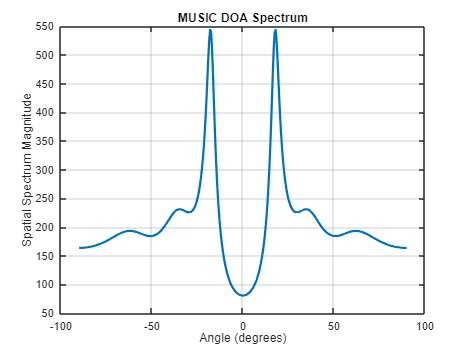

% Plot the DOA Spectrum
scanAngles = -90:0.5:90; % Define scan angles
figure;
plot(scanAngles, doaSpectrum, 'LineWidth', 2);
xlabel('Angle (degrees)');
ylabel('Spatial Spectrum Magnitude');
title('MUSIC DOA Spectrum');
grid on;


estim_ang_dft=[estimatedAngles(2);0];
estim_ang_cleanspeech=[estimatedAngles(4);0];
estim_ang_laughter=[estimatedAngles(6);0];

t_duration = 10;  % 10 seconds
t = 0:1/fs:t_duration-1/fs;

prevS = rng(2008);
noisePwr = 0*1e-4;
NSampPerFrame = 1000;
NTSample = t_duration*fs;

voice_dft = zeros(NTSample,1);
voice_cleanspeech = zeros(NTSample,1);
voice_laugh = zeros(NTSample,1);

% set up audio device writer
player = audioDeviceWriter('SampleRate',fs);


% dftFileReader = dsp.AudioFileReader("Female4.wav", ...
%     'SamplesPerFrame',NSampPerFrame);
% speechFileReader = dsp.AudioFileReader('Female2.wav', ...
%     'SamplesPerFrame',NSampPerFrame);
% laughterFileReader = dsp.AudioFileReader('Female3.wav', ...
%     'SamplesPerFrame',NSampPerFrame);
% 
% % simulate
for m = 1:NSampPerFrame:NTSample
    sig_idx = m:m+NSampPerFrame-1;
    x1 = dftFileReader();
    x2 = 0.5*speechFileReader();
    x3 = laughterFileReader();

    voice_dft(sig_idx) = x1;
    voice_cleanspeech(sig_idx) = 10*x2;
    voice_laugh(sig_idx) = x3;
 end
% %Notice that the laughter masks the speech signals, rendering them unintelligible. Plot the signal in channel 3.
% 
% plot(sigArray(:,3));
% xlabel('Time (sec)'); ylabel ('Amplitude (V)');
% title('Signal Received at Channel 3'); ylim([-3 3]);

signalsource = dsp.SignalSource('Signal',sigArray, ...
    'SamplesPerFrame',NSampPerFrame);

cbfOut = zeros(NTSample,1);
frostbeamformer = ...
    phased.FrostBeamformer('SensorArray',ula,'SampleRate',fs, ...
    'PropagationSpeed',c,'FilterLength',20,'WeightsOutputPort',true,'DirectionSource','Input port');
%Process and play the synthesized signal using the Frost beamformer.

frostbeamformer.DiagonalLoadingFactor = 1e-3;

reset(signalsource);
FrostOut2_dl = zeros(NTSample,1);
for m = 1:NSampPerFrame:NTSample
    temp = frostbeamformer(signalsource(),ang_dft);
    %player(temp);
    FrostOut2_dl(m:m+NSampPerFrame-1,:) = temp;
end

noise_estimate = mean(FrostOut2_dl(1:NSampPerFrame)); % Initial noise estimate
noise_reduced_output2 = wiener2(FrostOut2_dl, [NSampPerFrame 1], noise_estimate);

plot(FrostOut2_dl);
xlabel('Time (sec)'); ylabel ('Amplitude (V)');
title('Frost Beamformer Output');  ylim([-3 3]);

plot(noise_reduced_output2);
xlabel('Time (sec)'); ylabel ('Amplitude (V)');
title('Noise Reduced Output 1');  ylim([-3 3]);
% Calculate the array gain
agFrost2_dl = pow2db(mean((voice_dft+voice_laugh).^2+noisePwr)/ ...
    mean((noise_reduced_output2 - voice_cleanspeech).^2))

agFrost2_dl = -10.2295

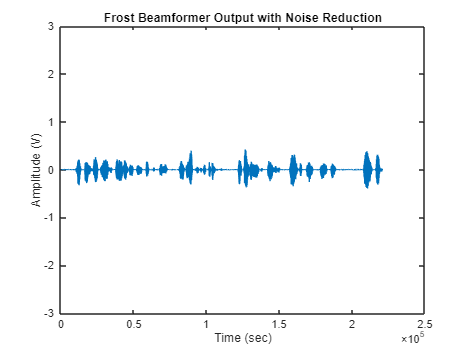

release(frostbeamformer);
frostbeamformer.DiagonalLoadingFactor = 1e-3;

reset(signalsource);
FrostOut1_dl = zeros(NTSample,1);
for m = 1:NSampPerFrame:NTSample
    temp = frostbeamformer(signalsource(),ang_cleanspeech);
    %player(temp);
    FrostOut1_dl(m:m+NSampPerFrame-1,:) = temp;
end

% Apply Wiener filter for noise reduction
noise_estimate = mean(FrostOut1_dl(1:NSampPerFrame)); % Initial noise estimate
noise_reduced_output = wiener2(FrostOut1_dl, [NSampPerFrame 1], noise_estimate);

plot(noise_reduced_output);
xlabel('Time (sec)'); ylabel ('Amplitude (V)');
title('Frost Beamformer Output with Noise Reduction');  ylim([-3 3]);

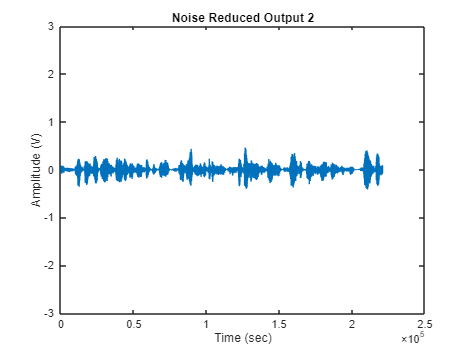

plot(FrostOut1_dl);
xlabel('Time (sec)'); ylabel ('Amplitude (V)');
title('Noise Reduced Output 2');  ylim([-3 3]);


% Calculate the array gain
agFrost1_dl = pow2db(mean((voice_dft+voice_laugh).^2+noisePwr)/ ...
    mean((FrostOut1_dl - voice_cleanspeech).^2))

agFrost1_dl = -10.3209

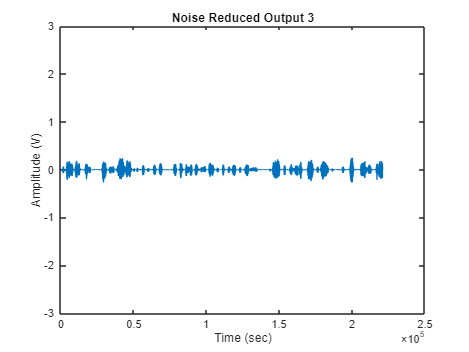

release(frostbeamformer);
frostbeamformer.DiagonalLoadingFactor = 1e-3;

reset(signalsource);
FrostOut3_dl = zeros(NTSample,1);
for m = 1:NSampPerFrame:NTSample
    temp = frostbeamformer(signalsource(),ang_laughter);
    %player(temp);
    FrostOut3_dl(m:m+NSampPerFrame-1,:) = temp;
end

% Apply Wiener filter for noise reduction
noise_estimate = mean(FrostOut3_dl(1:NSampPerFrame)); % Initial noise estimate
noise_reduced_output3 = wiener2(FrostOut3_dl, [NSampPerFrame 1], noise_estimate);

plot(noise_reduced_output3);
xlabel('Time (sec)'); ylabel ('Amplitude (V)');
title('Noise Reduced Output 3');  ylim([-3 3]);

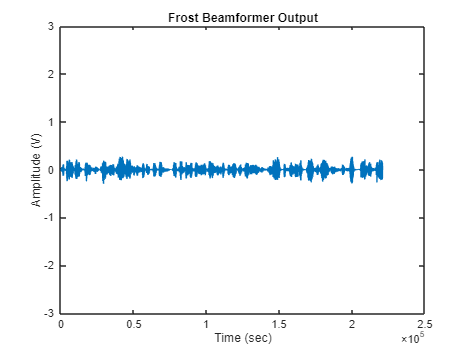

plot(FrostOut3_dl);
xlabel('Time (sec)'); ylabel ('Amplitude (V)');
title('Frost Beamformer Output');  ylim([-3 3]);


% Calculate the array gain
agFrost3_dl = pow2db(mean((voice_dft+voice_laugh).^2+noisePwr)/ ...
    mean((FrostOut3_dl - voice_cleanspeech).^2))

agFrost3_dl = -10.2985

release(frostbeamformer);
release(signalsource);
release(player);

rng(prevS);

mimoOutput= FrostOut3_dl+FrostOut2_dl+FrostOut1_dl;

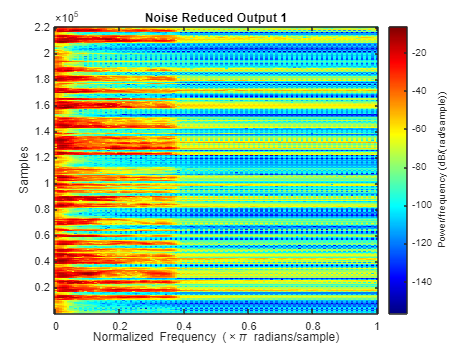


spectrogram(noise_reduced_output,128,120,256)
colormap jet;
title('Noise Reduced Output 1')

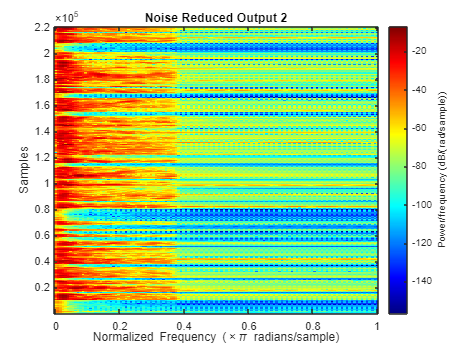

spectrogram(noise_reduced_output2,128,120,256)
colormap jet;
title('Noise Reduced Output 2')

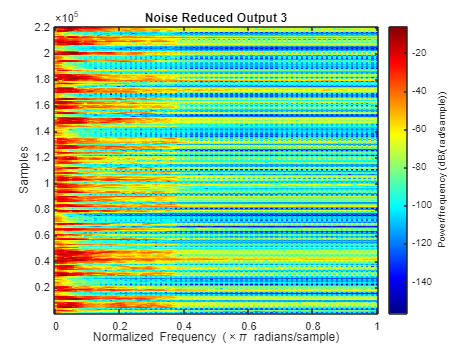

spectrogram(noise_reduced_output3,128,120,256)
colormap jet;
title('Noise Reduced Output 3')

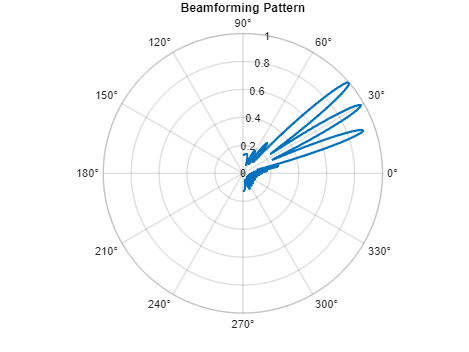

theta = -90:0.5:90; % Angle range for plotting
theta_rad = deg2rad(theta); % Convert to radians

% Define steering angles (Replace with your desired angles)
steer_angles = [ang_laughter(1,1), ang_cleanspeech(1,1), ang_dft(1,1) ]; % Example: Steer to -20° and 30°

% Compute beamforming weights
weights = zeros(Nele,1); % Initialize weight vector
for angle = steer_angles
    weights = weights + exp(-1j * pi * (0:Nele-1)' * sind(angle)); % Add steering contribution
end
weights = weights / length(steer_angles); % Normalize

% Compute array response
steering_matrix = exp(-1j * pi * (0:Nele-1).' * sind(theta)); 
beam_pattern = abs(weights' * steering_matrix); % Sum weighted responses

% Normalize and plot
beam_pattern = beam_pattern / max(beam_pattern); % Normalize to max 1
polarplot(theta_rad, beam_pattern, 'LineWidth', 2);
title('Beamforming Pattern');
rlim([0 1]); % Set radius limit
grid on;

collector = phased.WidebandCollector('Sensor', ula, 'PropagationSpeed', c, ...
    'SampleRate', fs, 'NumSubbands', 1000, 'ModulatedInput', false, 'WeightsInputPort', true);

% Simulate signal reception
for m = 1:NSampPerFrame:NTSample
    x1 = dftFileReader();
    x2 = speechFileReader();
    x3 = laughterFileReader();

    temp = collector([x1 x2 x3], [ang_dft ang_cleanspeech ang_laughter], weights);

    beamformed_sigArray(m:m+NSampPerFrame-1, :) = temp;
end

[independentComponents, mixingMatrix, unmixingMatrix] = customICA(beamformed_sigArray, 3)

Reconstruction Error: 8.6656
Max Component Correlation: 0.0000


independentComponents =    0.8482 + 0.5921i   0.1875 + 1.2001i   0.6422 + 0.2766i
   0.8033 + 0.5264i   0.1958 + 1.2533i   0.8671 + 0.4507i
   0.7447 + 0.6875i   0.2834 + 1.0912i   0.9055 + 0.4061i
   0.7599 + 1.0355i   0.4396 + 0.8498i   0.8354 + 0.1874i
   0.8666 + 1.3993i   0.5887 + 0.5544i   0.6979 - 0.1152i
   1.0302 + 1.5935i   0.6525 + 0.1622i   0.5001 - 0.3968i
   1.1951 + 1.5331i   0.6123 - 0.3004i   0.2604 - 0.5762i
   1.2956 + 1.2605i   0.5102 - 0.6730i   0.0376 - 0.6179i
   1.2588 + 0.8824i   0.3976 - 0.7563i  -0.0878 - 0.5284i
   1.0308 + 0.4895i   0.2906 - 0.4817i  -0.0646 - 0.3386i


mixingMatrix =   -0.0713 + 0.0930i  -0.1273 - 0.4020i   0.1620 + 0.4439i
  -0.2711 - 0.1163i   0.0162 + 0.1415i  -0.0585 - 0.2841i
  -0.0931 + 0.3226i   0.2539 - 0.7371i   0.0800 - 0.0958i
  -0.0510 - 0.2227i  -0.0216 - 0.1056i  -0.0520 - 0.0892i
   0.0395 - 0.3008i   0.0418 - 0.1860i  -0.0177 + 0.0267i
   0.0787 - 0.1838i   0.0023 - 0.0534i  -0.0991 + 0.1847i
  -0.0724 - 0.1352i  -0.0821 - 0.0041i  -0.0989 - 0.0397i
   0.1026 - 0.1338i  -0.0103 + 0.0029i  -0.1359 + 0.2618i
  -0.1005 - 0.2345i  -0.0294 - 0.1232i  -0.0370 - 0.1963i
  -0.0192 - 0.1666i  -0.0371 - 0.0409i  -0.0931 + 0.0125i


unmixingMatrix =   -0.0713 - 0.0930i  -0.2711 + 0.1163i  -0.0931 - 0.3226i  -0.0510 + 0.2227i   0.0395 + 0.3008i   0.0787 + 0.1838i  -0.0724 + 0.1352i   0.1026 + 0.1338i  -0.1005 + 0.2345i  -0.0192 + 0.1666i   0.0640 + 0.0268i  -0.0303 + 0.2027i  -0.0549 + 0.2356i  -0.1716 + 0.2925i   0.0196 + 0.2363i   0.0787 + 0.1879i  -0.0306 + 0.1615i   0.0727 + 0.1735i   0.0602 + 0.1839i   0.0897 + 0.1771i
  -0.1273 + 0.4020i   0.0162 - 0.1415i   0.2539 + 0.7371i  -0.0216 + 0.1056i   0.0418 + 0.1860i   0.0023 + 0.0534i  -0.0821 + 0.0041i  -0.0103 - 0.0029i  -0.0294 + 0.1232i  -0.0371 + 0.0409i  -0.0966 - 0.1295i   0.0009 + 0.0918i  -0.0263 + 0.1166i  -0.0183 + 0.1957i   0.0098 + 0.1170i   0.0185 + 0.0636i  -0.0538 + 0.0317i  -0.0094 + 0.0403i   0.0045 + 0.0580i   0.0164 + 0.0506i
   0.1620 - 0.4439i  -0.0585 + 0.2841i   0.0800 + 0.0958i  -0.0520 + 0.0892i  -0.0177 - 0.0267i  -0.0991 - 0.1847i  -0.0989 + 0.0397i  -0.1359 - 0.2618i  -0.0370 + 0.1963i  -0.0931 - 0.0125i  -0.1880 - 0.3144i  -0.0774 + 

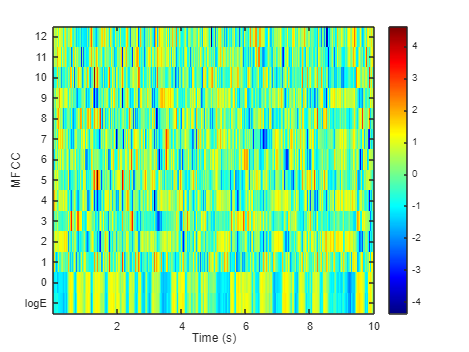

[coeffs1,delta1,deltaDelta1,loc1] = mfcc(noise_reduced_output,fs);
mfcc(noise_reduced_output,fs)
colormap(jet);

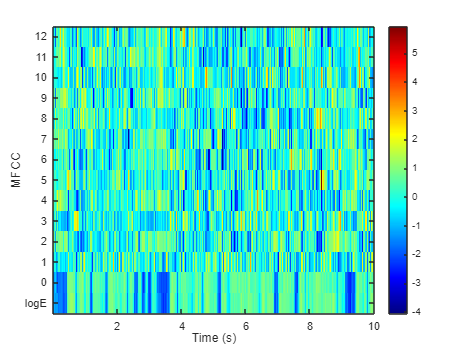

[coeffs2,delta2,deltaDelta2,loc2] = mfcc(noise_reduced_output2,fs);
mfcc(noise_reduced_output2,fs)
colormap(jet);

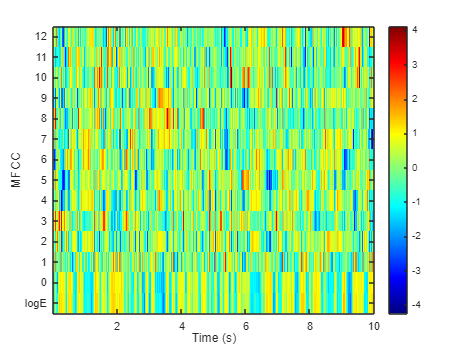

[coeffs3,delta3,deltaDelta3,loc3] = mfcc(noise_reduced_output3,fs);
mfcc(noise_reduced_output3,fs)
colormap(jet);


% Compute SDR before and after processing
sdr_before = compute_sdr(voice_cleanspeech, sigArray(:, 3)); % Before processing
sdr_after = compute_sdr(voice_cleanspeech, noise_reduced_output); % After beamforming and filtering


disp(['SDR Before Processing: ', num2str(sdr_before), ' dB']);

SDR Before Processing: -0.33306 dB


disp(['SDR After Processing: ', num2str(sdr_after), 'dB']);

SDR After Processing: -0.095596dB




% Compute SDR before and after processing
sdr_before = compute_sdr(voice_laugh, sigArray(:, 3)); % Before processing
sdr_after = compute_sdr(voice_laugh, noise_reduced_output); % After beamforming and filtering


disp(['SDR Before Processing: ', num2str(sdr_before), ' dB']);

SDR Before Processing: -6.1375 dB


disp(['SDR After Processing: ', num2str(sdr_after), 'dB']);

SDR After Processing: -2.7987dB



% Compute SDR before and after processing
sdr_before = compute_sdr(voice_dft, sigArray(:, 3)); % Before processing
sdr_after = compute_sdr(voice_dft, noise_reduced_output); % After beamforming and filtering


disp(['SDR Before Processing: ', num2str(sdr_before), ' dB']);

SDR Before Processing: -2.9386 dB


disp(['SDR After Processing: ', num2str(sdr_after), 'dB']);

SDR After Processing: -1.1215dB


% Compute SNR before and after processing
snr_before = compute_snr(voice_cleanspeech, sigArray(:, 3)); % Before beamforming
snr_after = compute_snr(voice_cleanspeech, noise_reduced_output); % After beamforming and filtering


disp(['SNR Before Processing: ', num2str(snr_before), ' dB']);

SNR Before Processing: -0.33306 dB


disp(['SNR After Processing: ', num2str(snr_after),'dB']);

SNR After Processing: -0.095596dB


% Compute SNR before and after processing
snr_before = compute_snr(voice_dft, sigArray(:, 3)); % Before beamforming
snr_after = compute_snr(voice_dft, noise_reduced_output); % After beamforming and filtering


disp(['SNR Before Processing: ', num2str(snr_before), ' dB']);

SNR Before Processing: -2.9386 dB


disp(['SNR After Processing: ', num2str(snr_after),' dB']);

SNR After Processing: -1.1215 dB


% Compute SNR before and after processing
snr_before = compute_snr(voice_laugh, sigArray(:, 3)); % Before beamforming
snr_after = compute_snr(voice_laugh, noise_reduced_output); % After beamforming and filtering

disp(['SNR Before Processing: ', num2str(snr_before), ' dB']);

SNR Before Processing: -6.1375 dB


disp(['SNR After Processing: ', num2str(snr_after),' dB']);

SNR After Processing: -2.7987 dB


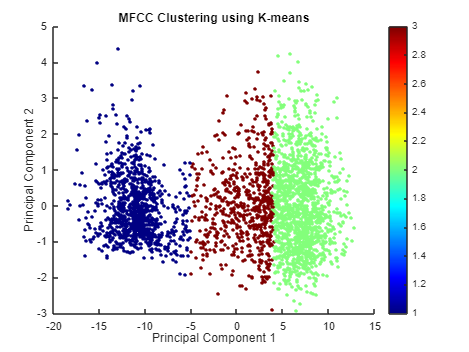

% Load the MFCC coefficients of 3 speakers (assume coeffs1, coeffs2, coeffs3)
features_speaker1 = coeffs1(:,:);
features_speaker2 = coeffs2(:,:);
features_speaker3 = coeffs3(:,:);

% Combine all MFCC features into a single matrix
mfcc_features = [features_speaker1; features_speaker2; features_speaker3];

% Number of clusters (equal to number of speakers)
num_clusters = 3;

% Apply k-means clustering
[idx, C] = kmeans(mfcc_features, num_clusters, 'MaxIter', 300, 'Replicates', 5);

% Visualize clusters using PCA
[coeff, score] = pca(mfcc_features); % Reduce dimensions
scatter(score(:,1), score(:,2), 10, idx, 'filled');
title('MFCC Clustering using K-means');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
colormap(jet);
colorbar;